# Calibration Curve

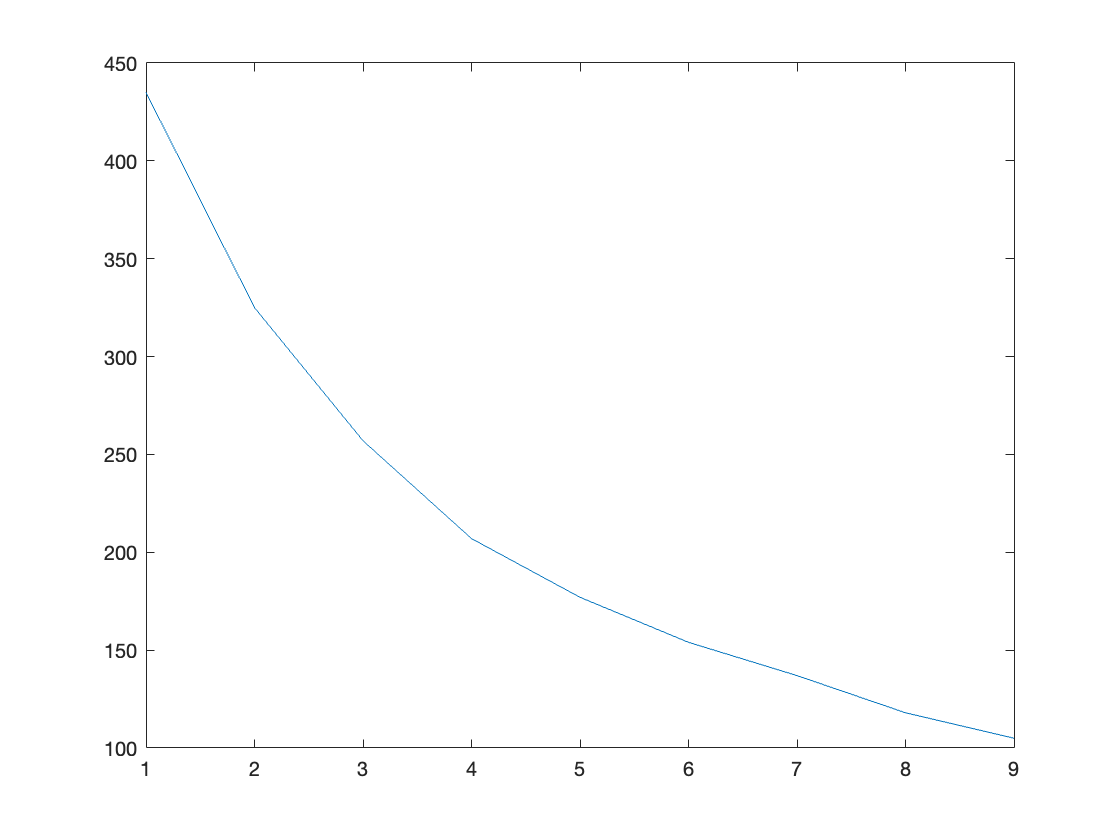

% Data measured
distances_cali = [20 30 40 50 60 70 80 90 100]';
measured_cali = [435 325 257 207 177 154 137 118 105]';
plot(measured_cali)

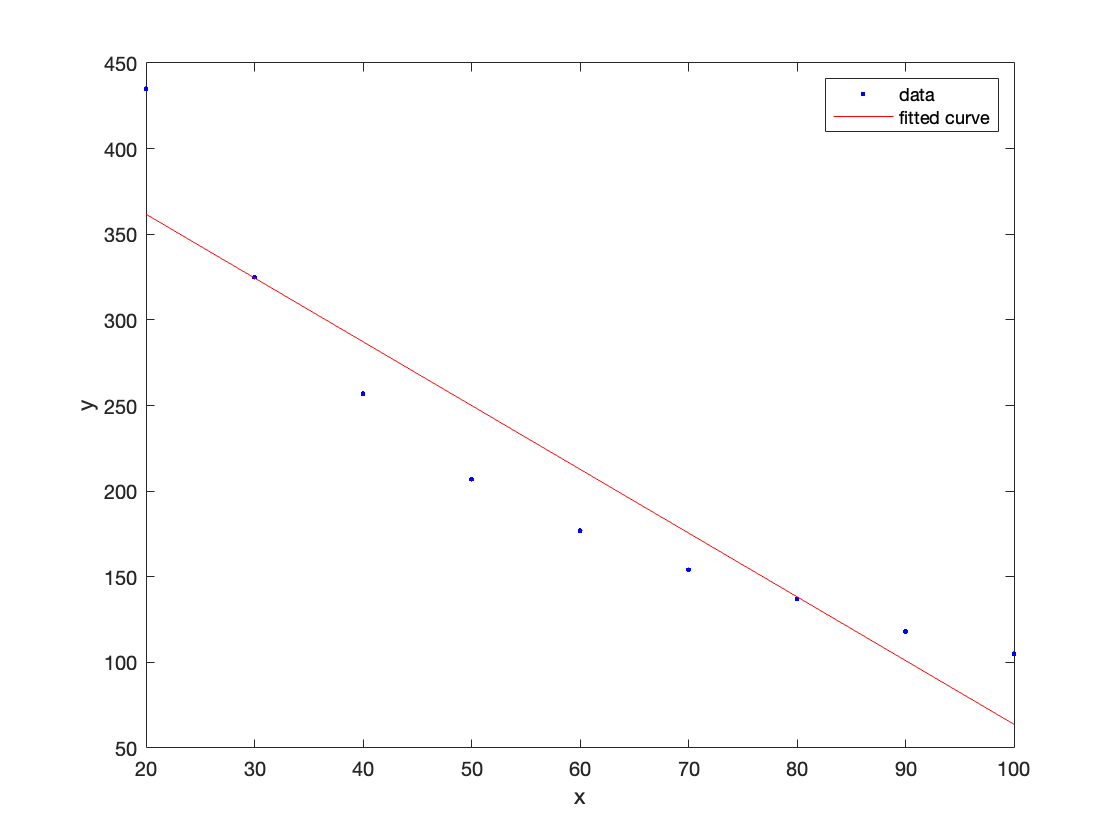

% Curve fitting - Linear
[f, gof] = fit(distances_cali,measured_cali,'poly1');
plot(f,distances_cali,measured_cali); % R-Sqaure: 0.8574

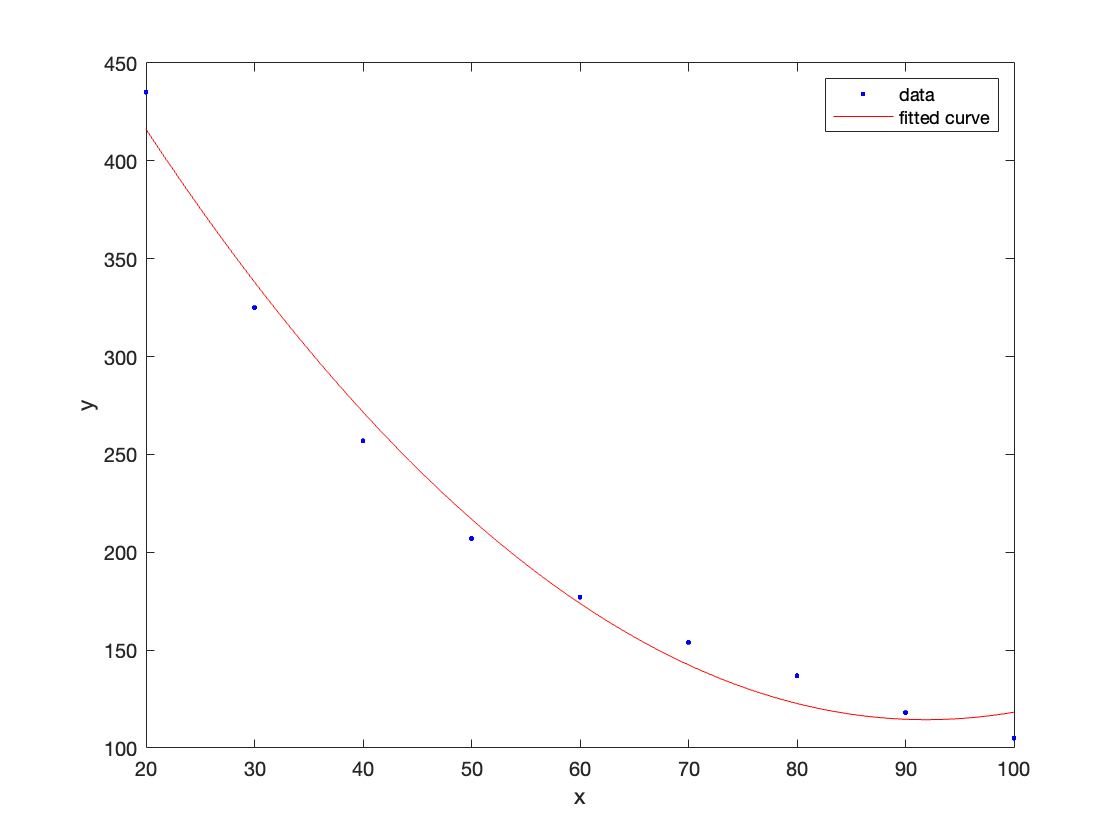

% Curve fitting - Polynomial
[f, gof] = fit(distances_cali,measured_cali,'poly2');
plot(f,distances_cali,measured_cali); % R-Sqaure: 0.9855

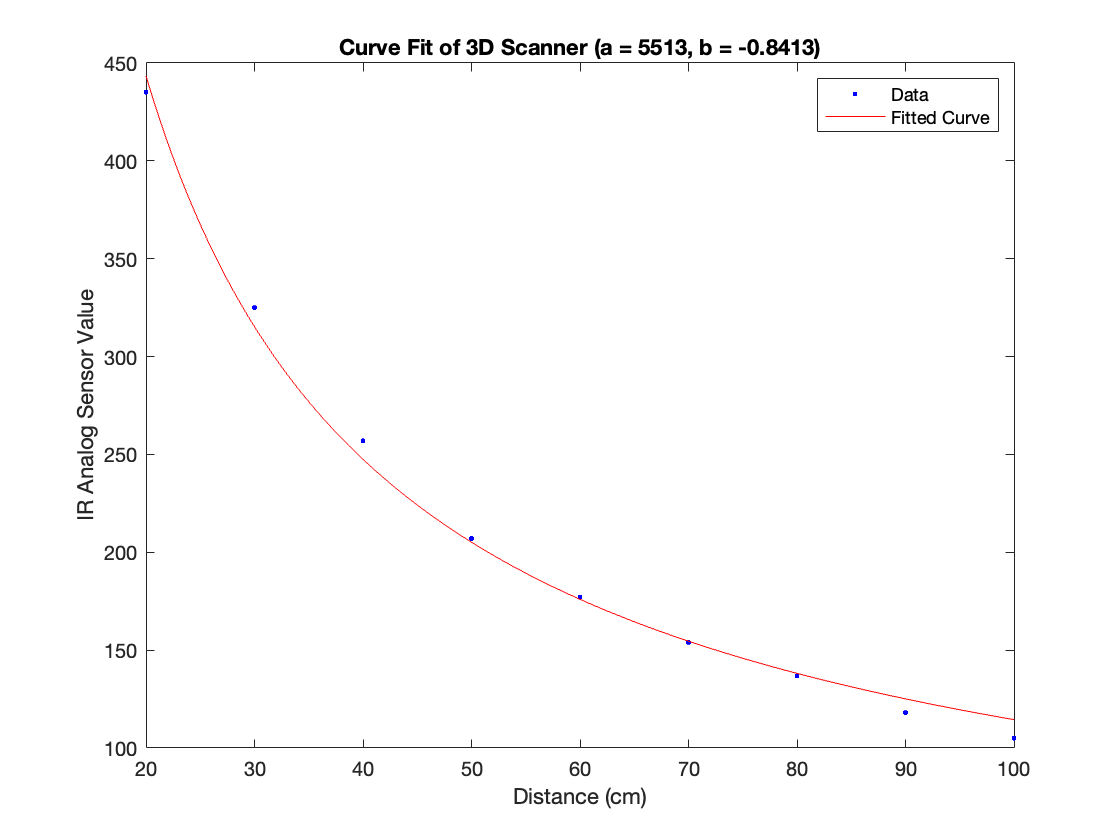

% Curve fitting - Power (Best Option)
[f, gof] = fit(distances_cali,measured_cali,'power1');
plot(f,distances_cali,measured_cali); % R-Sqaure: 0.9952 

title('Curve Fit of 3D Scanner (a = 5513, b = -0.8413)')
xlabel('Distance (cm)')
ylabel('IR Analog Sensor Value')
legend('Data', 'Fitted Curve')


% Equation -> f(x) = a*x^b
a = 5513;
b = -0.8413;

# Error Plot

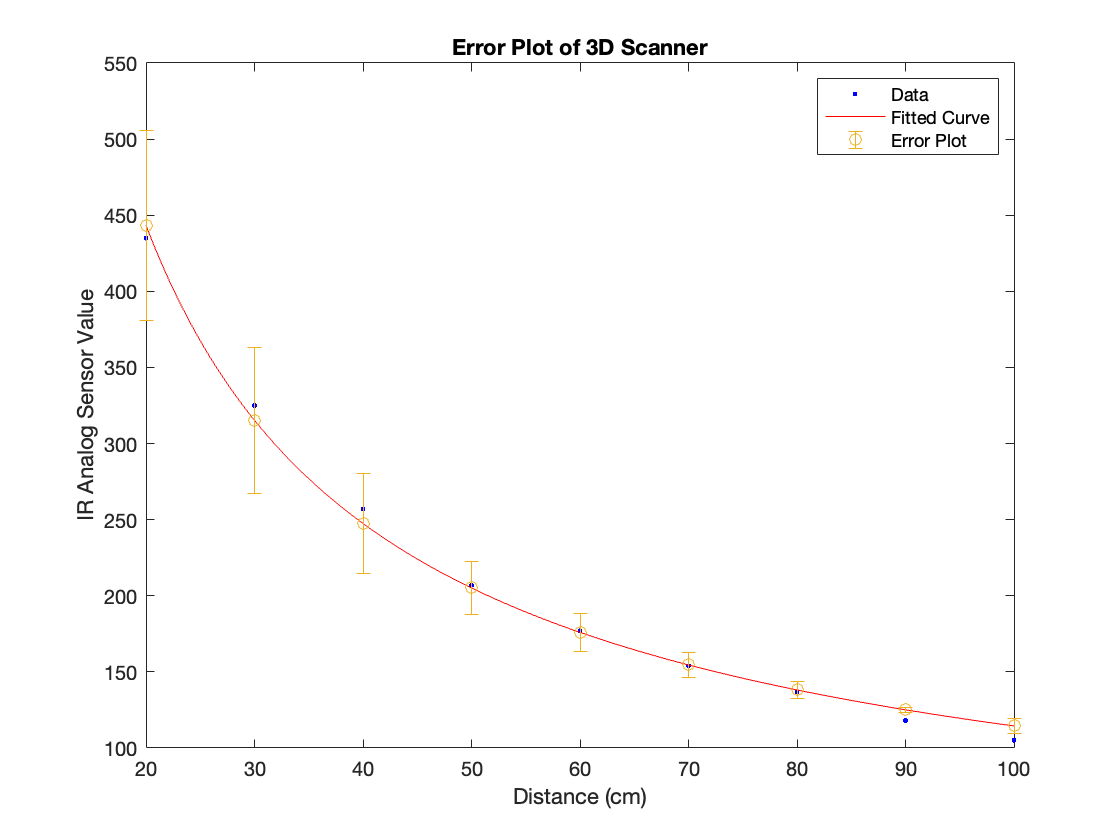

clear figure 

distances_error = [25 35 45 55 65 75 85 95 105]';
measured_error = [430 325 257 207 177 154 137 118 105]';

calculated_error = a*distances_error.^b;
error = measured_error - calculated_error;

x = 20:10:100;
f = a*x.^b;

hold on
errorbar(x,f,error', 'o');
title('Error Plot of 3D Scanner')
xlabel('Distance (cm)')
ylabel('IR Analog Sensor Value')
legend('Data', 'Fitted Curve', 'Error Plot')
hold off